# Assignment

## Task

In this assignment you will make a diffusion simulator that can calculate the concentration of particles across space and time. The model that you will use is a one-dimensional (1D) "random walk" model in which particles are located on a discrete grid of spatial coordinates from which they jump to adjacent grid points every time step. Fashion of those jumps is probabilistic, meaning that in each timestep particles will change location, either "left" or "right", with an equal probability (in the case without boundaries, e.g. Earth's surface). 

Such 1D random walk model, can be used to calculate the diffusion of molecules in three-dimensional (3D) space by applying the 1D random walk model in $x$, $y$, and $z$ directions. Probabilistic nature of random walk implies that random movements are independent in those three spatial directions, such that final location of particle in space is sum of random jumps in "left-right", "forward-backward", and "up-down" directions. 

In a series of questions here, you will develop the 3D diffusion simulator starting with 1D random walk model and expanding it to three dimensions. Simulator will have functionality to simulate **any** kind of pollution source - point (e.g. smoke stack), line (e.g. road), area (e.g. burning forest), and volume source (e.g. clouds of dust coming from uncoverd piles of coal, sand, ore, etc.).

Furthermore, you will develop tools for visualisation of statistics of pollutants both in time and space. 

**NOTE: **try to restrain yourself from using `for` loops if [there is a way](https://au.mathworks.com/help/matlab/matlab_prog/vectorization.html) to do the same job without them. 

**NOTE: **you will write functions in separate files. In those files I started the function and made a comment on how many lines of code it took me to write the function. That comment is just a guide for you. If your code has more lines than mine it is okay, as long as the code does the job. In the line count I don't take into account the `for` loop statements. E.g.

`for i = 1:5`

    `j = i*4;`

    `disp(j);`

`end`

I count as two lines (ones within the loop, first and last line are omitted from my "line count") 

**NOTE: **you will know whether the function does the job it is supposed by running the tests. For some functions I already made tests that are in `tests.mlx` file. So, once you write the function, run the test for that function, and if test section does not return any messages then tests passed and your function probably does what is supposed to do. 

## How does the 1D simulator work?

Simulator simulates random movements of discrete particles across the number of time-steps $k$. As an output it gives the one dimensional array (row vector) of particles' locations measured in meters from the origin, we will name that array `locations`. In such an array first element is location of the particle 1, second element of the array is the location of the particle 2, etc. Array has $n$ elements, where $n$ is the number of particles in simulation.

In the case where we have $n=4$ one of the possible outputs would look like:

`locations -> [-3.2, 4.11, -1.1, 0.223]`

Simulation starts with the generation of initial particles' locations at the source. In general, "source functions" generate array with locations of new particles, where logic of function depends on type of the source, e.g. point source function will generate $m$ new particles at the coordinate of source, and line source will generate $m$ new particles equally spaced between the starting and ending point of the line. In the case where points source function generates $5$ new particles at coordinate $1.5$ output of the `PointSource` function would like:

`new_locations -> [1.5, 1.5, 1.5, 1.5, 1.5]`

In the case of `LineSource` function that generates 3 particles on the line between coordinates $-1.0$ and $1.0$ output would look like:

`new_locations -> [-1.0, 0., 1.0]` 

Once new particles are generated `locations` array has to be updated such that new locations are appended to `locations` array. We will use the `AddLocations` functions to update `locations` array with `new_locations.` In a situation where we had locations of $3$ particles in previous steps e.g. $[-1.2, 0.2, 0.8]$, and where we generated $3$ new particles in current step with `LineSource` function, e.g. $[-1.0, 0., 1]$, output of `AddLocations` function would look like:

`locations -> [-1.2, 0.2, 0.8, -1.0, 0., 1]` 

### What happens in a single time-step?

In each time-step locations of particles are updated according to the rules of the random walk and wind advection.

Once we have `locations` array (either from previous step or newly made by source) we have to update the locations of particles. We will use `RandomJump` function for that. In one dimension particle moves either "left" or "right" with 50/50 probability. Thus updater randomly subtracts or adds the length of manually assigned random jump from the locations in `locations` array. In the case where jump is $0.1\mathrm{m}$ and old locations are as in previous step, possible output of `RandomJump` function may look like:

`locations -> [-1.2-0.1, 0.2+0.1, 0.8+0.1, -1.0+0.1, 0.-0.1, 1+0.1] =`

`             = [-1.3, 0.3, 0.9, -1.1, -0.1, 1.1]`

After taking into account the random jump, our simulator will take into account the boundaries. We will manually assign the coordinates of "left" and "right" boundaries. Boundaries are bouncy, meaning that particles elastically bounce from the boundary. Thus, the `Boundary` function will take the `locations` and will update the position of the particles that are beyond the boundaries in such way that path covered by the bounced particle amounts to the value of the jump. E.g. let's say that we have left boundary at the coordinate $-2\,\mathrm{m}$, jump of $0.2\,\mathrm{m}$ and particle that started at the coordinate $-1.95\,\mathrm{m}$ and after calling `RandomJump` function ended over the boundary at the coordinate $-2.15\,\mathrm{m}$. Now, we know where it should've ended; we know that in reality it travelled for $0.05\,\mathrm{m}$to the lef, encountered the boundary, bounced off, and travelled for $0.15\,\mathrm{m}$to the right, such that travelling distance is equal to the length of jump. This reults in the particle being at the coordinate $-1.85\,\mathrm{m}$. Thus, function `Boundary` should update the location of that particle from $-2.15\,\mathrm{m}$ to $-1.85\,\mathrm{m}$.   

Next step is to take into account the wind advection where particles are carries by the wind with the manually assigned velocity $u$. Sign of the velocity determines the direction of the wind, negative for blowing "left" and positive for blowing "right". In the case where wind blows right with the velocity of $0.5\,\mathrm{m/s$ and where time-step has duration of $0.5\,\mathrm{s}$, updated locations of `locations` array $[-1.1, -2.7, 0.3, 4.8]$ would look like:

`locations -> [-0.85, -2.45, 0.55, 5.05]`

**NOTE:** For the simplicity, you will have to make sure that wind does not blow towards the boundary if it exist.

### 1D Simulator Engine

Now, we know what happens in one time-step. Simulator engine will take the duration of time-step, $\Delta t$ and a number of time-steps $k$ for which we want to run the simulation, and it will repeat the procedure described above $k$ times. We will wrap the prcedure in `OneDimEngine` function that will take `struct` container named `engine_parameters` that has all of the needed parameters for the simulations. Those parameters are then forwarded to functions described above. In the end, `OneDimEngine` returns the `locations` of particles along the single direction.

In this assignment we will make two types of engines - first `OneDimInstantEngine` for instantaneous release of pollutants from a source and second `OneDimContEngine` for sources that generate pollutants continuously. 

### ND Simulator Engine

Once we have a 1D engine we can reuse the `OneDimEngine` to calculate the dispersion in any number of directions we want, since movements in different directions are independent of each other. Our `NDimEngine` will take a containers.Map container that has up to three keys, either `'X'`, `'Y'`, or `'Z'`. Depending on keys in container, the engine will behave like either 1, 2, or 3 dimensional engine. Value of the key is set of `engine_parameters` for the respective direction. In addition to direction keys, it will have key  `'release` that will have value either `'instant' `or `'cont' `depending on which the simulator will pick right one dimensional engine for a job. 

`NDimEngine` returns the `locations_map` container with keys either `'X'`, `'Y'`, or `'Z' `where the value assigned to the key is `locations` array with the locations of particles in that respective direction.

## 1D random walk simulator

### 1 Source

#### Question 1a) Point source (0.75 points)

Make a function `PointSource` that takes `source_parameters` struct container. `source_parameters` has fields `'x'` and `'n'`. Field `'x'` represents coordinate of point source and field `'n'` represents number of particles generated at the source. Output of function `PointSource` is one dimensional array of locations of `n` particles.

% go to file PointSource.m and define the function there
new_locations = PointSource(source_parameters);

Unrecognized function or variable 'source_parameters'.

#### Question 1b) Line source (0.75 points)

Make a function `LineSource` that takes `source_parameters` struct container. `source_parameters` has fields `'start'`,  `'end'`, and `'n'`. Field `'start'` is a starting point of line, field `'end'` is ending point of the line, and  field `'n'` represents number of particles generated along the line at equal distances. Output of function `PointSource` is one dimensional array of locations of `n` particles.

% go to file LineSource.m and define the function there
new_locations = LineSource(source_parameters);

#### Question 1c) Append new particles to array of existing particles (0.5 points)

Make a function `AddLocations` that will append array with locations of newly generated particles to the array `locations` that has locations of all particles. 

% go to file AddLocations.m and define the function there
updated_locations = AddLocations(new_locations, locations);

#### Question 1d) Source strategy pattern (1 point)

We want our code to be modular and smart, meaning that it can choose the right function to generate new particles by passing the parameter that will tell the simulator which source function to use. In that way, we can write only one engine function that will pick the right strategy depending on our preferences. Your task is to make the `SourceStrategy` function that will take the string `source_type` and return the right function to do the job. `source_type` string can have values `'line'` or `'point'`. If `'line'` is passed as parameter then `SourceStrategy` returns the `LineSource` function. If the parameter is `'point'` then function returns the `PointSource` function.

Before writing this function make sure to check the `function_handlers.mlx` notebook in which you will learn how to store functions as variables that can be reused and passed to another functions.

% open notebook function_handlers.mlx to learn things you need for this task
% then go to file SourceStrategy.m and define the function there
source_func = SourceStrategy(source_type);

#### Question 1e) Source wrapper (1.5 points)

Following function `GenerateFromSource` is a wrapper for functions defined above. It is a convenient way of assigning a responsibility of dealing with newly generated particles to a single function. This function takes `source_parameters` struct container and `locations` array as arguments. `source_parameters` has fields that "source functions" need. It returns the updated array of locations. 

For example `source_parameters` struct can have following.

- `source_parameters.strategy = 'line'`

- `source_parameters.start = -1.5`

- `source_parameters.end = 2.2`

- `source_parameters.n = 500`

Such `source_parameters` struct container tells the wrapper to generate 500 hundred new particles along the line starting at coordinate $-1.5\,\mathrm{m}$ and ending at the coordinate $2.2\,\mathrm{m}$

% go to file GenerateFromSource.m and define the function there
updated_locations = GenerateFromSource(source_parameters, locations)

### 2 Random walk

#### Question 2a) Updating position of particles after single timestep (0.75 points)

Make a function `RandomJump` that takes two arguments - struct `jump_parameters` and locations of particles.  `jump_parameters` struct has field `'jump'` that is a length of a random jump in meters. Function updates the locations in array of particle locations such that location of each particle is changed randomly for `±jump.`

% go to file RandomJump.m and define the function there
updated_locations = RandomJump(jump_parameters, locations)

#### Question 2b) Boundaries - bouncing boundary (0.75 points)

Domain may, or may not, have boundaries that prevent molecules from passing through. Here we deal with two types of boundaries: bouncing and sticky boundaries. Bouncing boundaries are such that molecules bounce from the boundary if they encounter it.

Make a function `Boundary` that takes the struct `jump_parameters` and array of particle locations. `jump_parameters` struct has fields `'left',` `'right'`. Field `'left'` is a coordinate of left boundary and field `'right'` is a coordinate of the right boundary. Function updates the location of the particles that crossed the boundary such that particle's travel length amounts to the value of the jump (see introduction section for clarification)

Function must work for the case when there is no boundaries, as well for the case with boundaries. What is the coordinate of "boundary" if boundary does not exist?

% go to file Boundary.m and define the function there
locations = Boundary(boundary_parameters, locations)

### 3 Wind

#### Question 3a) Wind advection (1 point)

Make `WindAdvection` function that takes the `wind_parameters` struct and `locations` array as arguments. `wind_parameters` has fields `'u_func'` and `'dt'`. Field `'u_func'` is a function handler of a wind velocity function that returns the wind velocity for a given coordinate in meters per second. Sign of the wind velocity value encodes wind blowing left if sign is negative and wind blowing right if the sing is positive. Field `'dt'` is duration of the time-step. 

Function returns the array of updated locations of particles such that the old locations are updated with the distance traveled in time `'dt'`.

% go to file WindAdvection.m and define the function there
updated_locations = WindAdvection(wind_parameters, locations);

### 4 Engines

#### Question 4a) One dimensional engine - instantaneous release (1.25 points)

Make a function `OneDimInstantEngine` that takes the struct container `engine_parameters` as an argument in which the simulation parameters are stored. Container has fields: 

- `'k'` - number of timesteps to simulate

- `'dt'` - time-step

- `'n'` - number of particles released at the beginning of the simulation

- `'source_type'` - string with the name of source type (either "point" or "line")

- additional fields depending on `source_type` - e.g. `'x'` if we we deal with point source, `'start'` and `'end'` if dealing with line source.

- `'jump'` - random walk jump in between the timesteps

- `'left'` - coordinate of left boundary

- `'right'` - coordinate of right boundary

- `'u_func'` - function handler for a function that returns wind velocity at given location 

Function should generate `n` number of particles and let the particles diffuse throughout the `k` number of time-steps. 

% go to file OneDimInstantEngine.m and define function there
locations = OneDimInstantEngine(engine_parameters);

#### Question 4b) One dimensional engine - continuous release (1.25 points)

Similar to previous question except the function `OneDimContEngine` should generate `n` number of particles in each time-step.

% go to file OneDimContEngine.m and define function there
locations = OneDimContEngine(engine_parameters)

## N-D Random Walk Simulator

#### Question 4c) N-dimensional engine (2.5 points)

Make an `Engine` that takes `simulation_parameters_map` variable that is of type containers.Map that has up to three keys, either `'X'`, `'Y'`, or `'Z'`. Depending on keys in container, the engine will behave like either 1, 2, or 3 dimensional engine. Value of the key is set of `engine_parameters` for the respective direction. Don't forget that difussion in each direction is calculated independently from the rest of directions. As second argument, E`ngine` function takes type of release as string e.g. `'cont'` or `'instant'` and picks the right one-dimensional engine for the job.

Function should return containers.Map that has keys `'X'`, `'Y'`, or `'Z'` and where the values are `locations` arrays. 

Let's suppose that we want to simulate the two dimensional diffusion in vertical and horizontal direction. In that case `simulation_parameters_map` would look like:

`simulation_parameters_map = containers.Map({'X','Z'}, {engine_parameters_x, engine_parameters_z})`

Where `engine_parameters_x` and `engine_parameters_z` are struct fields as described in previous question. Output of `Engine` in that case would look like:

`locations_map = containers.Map({'X', 'Z'}, {locations_x, locations_z})`

% go to Engine.m and define the function there
locations_map = Engine(simulation_parameters_map, sim_type);

## 5 Visualisation

#### Question 5a) One-dimensional histogram (3 points)

Make a function `ConcentrationHist` that takes one dimensional array of `locations` and shows a bar chart depicting number of particles in bin. E.g. number of particles between -0.5 and 0.5 [m], 0.5 and 1.5 [m]... Name the $y$ axis concentration, and $x$ axis should be coordinate of a direction for which we are doing statistics (either $x$, $y$, or $z$).

Function `ConcentrationHist` takes two arguments. First one being `hist_parameters` - a struct container with fields needed for plotting of histogram. And second one being `locations` of one dimensional array with coordinates of particles. Function returns figure object.

`hist_parameters` struct has following fields:

- `'start'` - start coordinate for binning

- `'end'` - end coordinate for binning

- `'n'` - number of bins

- `'direction'` - string that represents the direction in which we are binning e.g. `'z'`

- `'unit'` - string representing the unit of measurement (will be printed as part of vertical axis label) e.g. (`'kg/m'` or `'ppmv'` or `'mg/m^3'`, etc.

- `'factor'` - conversion factor between the count in the bin and concentration expressed in `'unit'`

% go to ConcentrationHist.m and define your function there
f = ConcentrationHist(hist_parameters, locations);

## **6 Modeling scenario - Accidental release of carbon monoxide from a bathroom boiler (2.5 points)**

Ann heard a sudden sound of something falling in the bathroom where her granddad was taking a shower. As she went to see what happened, she asked her granddad whether he is okay but there was no response. Ann, sensing that something bad happened, opened a door of bathroom, and immediately started feeling dizzy. Not willing to risk her health, she ran out of her house and called 000. When explained what happened, fire brigade was sent to a scene. Experienced and very smart firey realised that this is probably a case of carbon monoxide poisoning and immediately shut the gas valve that was supplying 5 kW natural gas boiler that worked for 15 minutes before the valve was shut. Yet, he was afraid to enter the house even with the oxygen mask because the carbon monoxide is highly poisonous even in small amounts - it binds to hemoglobin preventing the oxygen from reaching the lungs and, if there is a source of energy, carbon monoxide binds to oxygen and converts to carbon dioxide that can suffocate humans if concentration is too high. For that reason, firey had an idea to open two large sliding doors, one leading to a backyard and second being the garage door, and letting the carbon monoxide to diffuse out of the house. Problem is that he would've used fans to suck the carbon monoxide fast but fans are currently on other job and can arrive to the scene in two hours. 

He called you as a consultant to tell him whether the house is going to be safe to enter in two hours time, because if it is, he will not call for fans to arrive. Also, he is interested, what area he has to evacuate in order to let carbon monoxide to diffuse, that is - what is the radius in which carbon monoxide has concentrations hazardous for human health. 

Having those two questions on your mind, you decided to run a simulation. You made some calculations and worst case scenario of boiler malfunction showed that in 15 minutes boiler produced $142.5\,\mathrm{g}=5.09\,\mathrm{mol}$ of carbon monoxide. You decided to model this as instantaneous release from a point source at the location of boiler $(x,y,z)=(0,5,2)\,\mathrm{[m]}
$. House is modeled as rectangular cuboid (box), bounded by floor and ceiling at $z$ coordinates $0\,\mathrm{m}$and $3\,\mathrm{m}$, and by walls in $y$ direction at coordinates $-5\,\mathrm{m}$ and $5\,\mathrm{m}$. In $x$ direction walls are at coordinates $-5\,\mathrm{m}$ and $5\,\mathrm{m}$. Since firey plans to open the garage and backyard doors that are on the walls in $x$ direction, you'll treat this direction as without boundaries. 

Temperature of air is $20\,^{\circ}\mathrm{C}$. In ideal conditions, diffusivity, $D$, of carbon monoxide in air at $20\,^{\circ}\mathrm{C}$ is $0.208\,\mathrm{cm^2/s}$. For diffusivity $D$ and time-step $\Delta t$ random jump length is given with $\sqrt{2D\Delta t}$. But due to the turbulences in air assume that jump value is 10 times larger that one calculated for ideal conditions.

Due to the built up air pressure inside the house there will be wind advection once the doors are opened. Wind velocity function in $x$ direction is given with equation


$$\[
  u =
  \begin{cases}
                                   0 & \text{if $x=0$} \\
                                   \mathrm{sign}(x)0.005\mathrm{exp}\left(\frac{-x^2}{20}\right) & \text{if $x \neq0$} 

  \end{cases}
\]$$
   

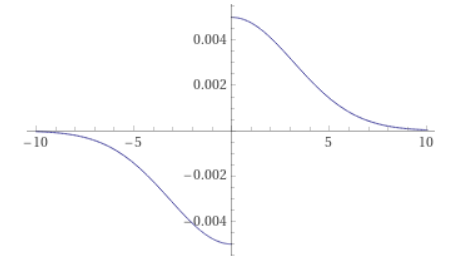

I hid similar function somewhere around the files you have here in a working folder. Try to find it and copy paste it if you are not sure how to make your own...

Set the timestep of simulation to 10 seconds and treat a single particle as a package of molecules that weigh$10\,\mathrm{mg}$.

What is the maximum concentration of carbon monoxide inside the house after two hours? Read the value from the graph!**(1.25 points)**

Firey is willing to accept concentrations below $100\,\mathrm{ppmv}$ since by law they are allowed to spend maximum of half an hour in space with that concentration. Is he allowed to enter the house? For the safety of citizens he puts bit more stringent requirements - limiting values of carbon monoxide concentrations to $30\,\mathrm{ppmv}$. 

What is the radius measured from the source of carbon monoxide in which concentrations of it are above that limit after two hours? Read the value from the graph! **(1.25 points)**

Read the values from the graphs, generated by visualisation functions. Graphs that you will read concentrations from should look similar to this (I ommited units and labels on purpose, though the shape should be similar):

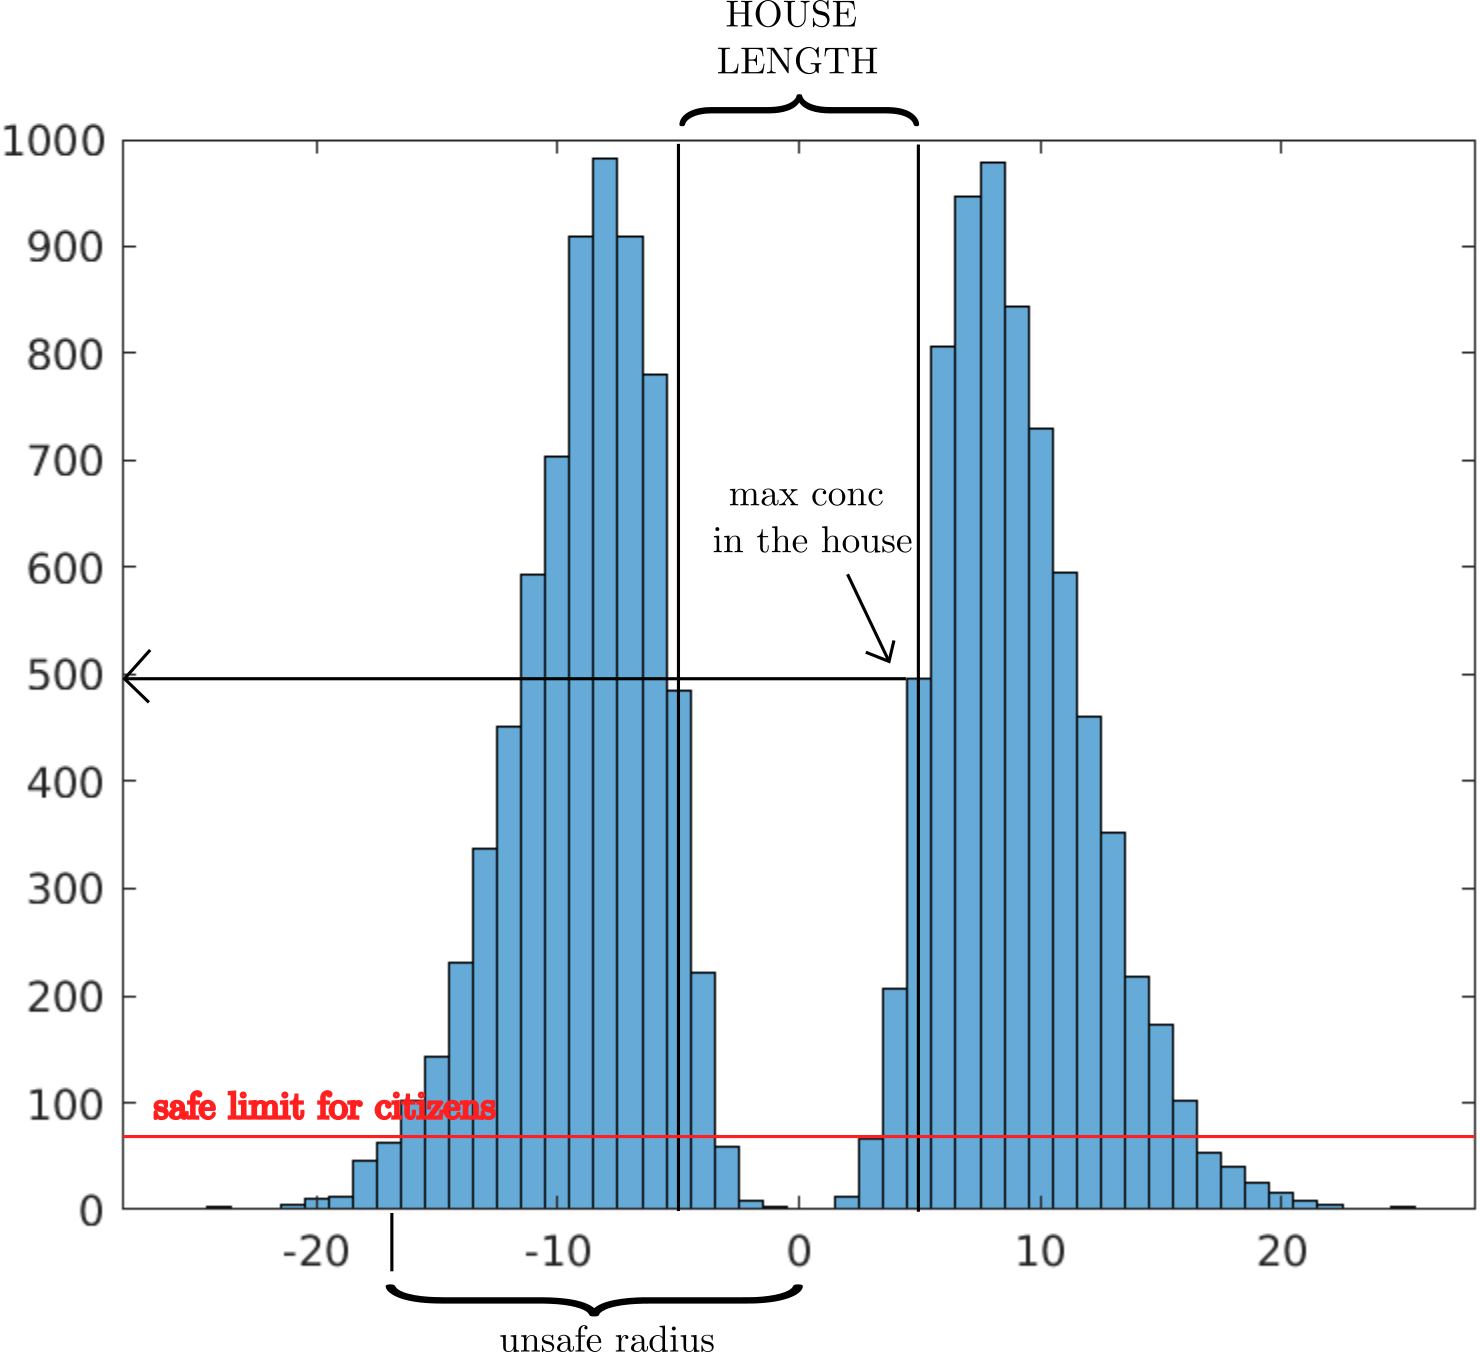

In this case I read maximum concentration in house to be 500 of something. And from second graph I read that the radius in which concentrations are above 30 ppmv limit is approx 17 meters.

% Your code here

## 7 Modelling scenario - Long term pollution from a road (2.5 points)

Citizens of Marramarra village in rural NSW are concerned that the air quality in their village is affected by caravans of heavy duty diesel dump trucks going day and night from the coal mine nearby. They are mostly concerned with the primary school whose playground is 100 meters West from the road. Road that goes through the village is 200 m long and is oriented NW-SE. Average wind speed in that region is 3 meters per second and direction of the wind is E. Road is the line source where the release height of the pollution is 3 meters. Each hour 100 trucks go past that road. Each truck travels with the speed of 50 kilometers per hour. Truck's engine power is 550 horsepowers and NOx production of engine is 2 grams per kWh of useful energy. 

Place the origin of coordinate system in the center of the road such that $x$ axis faces East, $y$ axis faces North, and $z$ axis faces up starting from the ground. Coordinates of school are $(-100, 0)$. Set the time-step of simulation to 10 seconds. Generate 1000 particles in each time-step.

How much NOx per meter of road is generated by trucks each second?

Calculate NOx concentration in micrograms per litre, $\mathrm{\mu g/L}$, at school's playground measured 1 m above the ground. To get the concentration, count the number of particles in "box" 2 meters high, 20 m long and 20 m wide centered around the school, and convert the count to $\mathrm{\mu g/L}$. 

% your code here

## 8 Easter eggs

### Easter egg 1 (7 points)

We made a `LineSource` function that generates the particles along the line with particles being at equal  distances. That, works but it would be nice to have function that would randomize the locations of generated particles along the line such that distances between the particles are not the same and that those distances are different every time the function is called. Make a function `EasterEgg1` that returns the one dimensional array of locations of newly generated particles in one direction. 

First you will call the `EasterEgg1` to generate the locations of random $x$ coordinates along the line, and then you will call the `EasterEgg1` function to generate the locations of $y$ coordinates such that particles are on the same line. It may seem easy, but here is the trick - when you generate $y$ locations the function `EasterEgg1` must be unaware of the $x$ coordinates of particles. **That is, you must not pass the locations of **$x$** coordinates to **`EasterEgg1`** function when generating **$y$ **coordinates and vice-versa.**

Let's say we want to generate 3 particles along the line that has start coordinates $(1,0)$ and end coordinates $(3,2)$ Sample output may look like this:

`EasterEgg1(x_start, x_end, maybe_some_other_arguments) -> [0.8, 1.55, 2.95]`

`EasterEgg1(y_start, y_end, maybe_some_other_arguments) -> [-0.2, 0.55, 1.95]`

I am allowing you to have starting and ending points outside of the domain (but still on the line)!

% go to EasterEgg1.m and define function there

### Easter egg 2 (2 points)

Make a AreaSource function that returns the locations of newly generated particles in a given direction. **Function must be unaware of coordinates in other directions. **Locations of particles may or may not be random (depends on you).

% go to EasterEgg2.m and define function there

% show that code works - generate locations of new particles for three dimensions such
% that location_x is array of particle x coordinates, location_y is array of 
% particle y coordinates, and location_z is array of particle z
% coordinates. Let the area source have limits in x direction start=-2,
% end=3, in y direction start=0, end=5, and z coordinate of area source is 0.  
% Generate 10^2 particles

### Easter egg 3 (1 point)

Make a `VolumeSource` function that returns the locations of newly generated particles in a given direction. **Function must be unaware of coordinates in other directions. **Locations of particles may or may not be random (depends on you).

% go to EasterEgg3.m and define function there

% show that code works - generate locations of new particles for three dimensions such
% that location_x is array of particle x coordinates, location_y is array of 
% particle y coordinates, and location_z is array of particle z
% coordinates. Let the area source have limits in x direction start=-2,
% end=3, in y direction start=0, end=5, and in z direcion start=0, end=1.
% Generate 10^3 particles

### Easter egg 4 (2 points or 5 points)

Make a function `EasterEgg4` that will plot two dimensional histogram in a plane of your choice for within the limits in off-plane direction (if it exists). Function takes `hist_parameters` struct and `locations_map` as arguments and returns the figure of 2 dimensional histogram. 

`hist_parameters` has, at least, following fields:

- `'hist_plane'` - string that can have values either `'XY'`, `'YZ'` or `'XZ'`. It represents the plane in which we want to show concetrations.

- `'start_1'` - start coordinate for binning in first direction, e.g. $y$ direction if `hist_plane` is `'YZ'`

- `'end_1'` - end coordinate for binning in first direction

- `'start_2 - `start coordinate for binning in second direction, e.g. $z$ direction if `hist_plane` is `'YZ'`

- `'end_2'` - end coordinate for binning in second direction

- `'n_1'` - number of bins in first direction

- `'n_2'` - number of bins in second direction

- `'unit'` - string representing the unit of measurement (will be printed as part of vertical axis label) e.g. (`'kg/m^2'` or `'ppmv'` or `'mg/m^3'`, etc.

- `'factor'` - conversion factor between the count in the bin and concentration expressed in `'unit'`

- `'limit_down' - out of plane down limit e.g. when we want to plot concentrations in 'XY' plane where `$z$ is larger than 1 meter then we would set this limit to 1

- `'limit_upper'` - out of plane upper limit e.g. when we want to plot concentrations in 'XY' plane where $z$ is smaller than 3.5 meters then we would set this limit to 3.5

% go to EasterEgg4.m and define function there

Output should look like this (I ommited labels) **2 points:** 

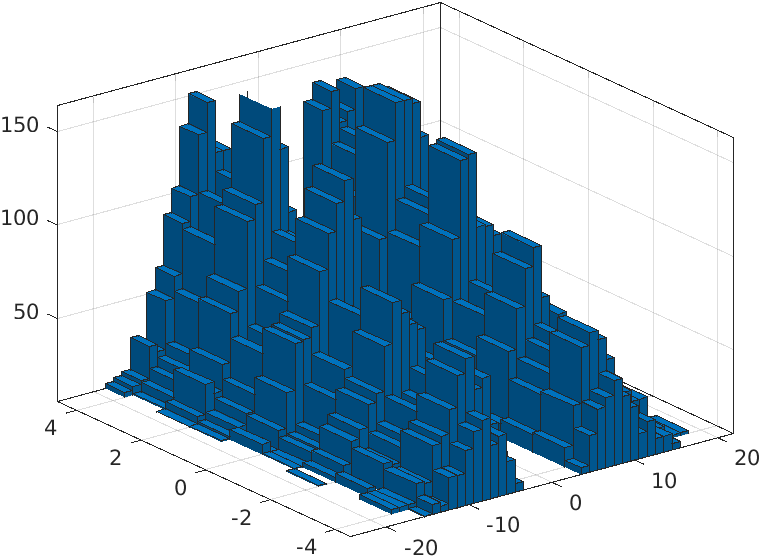

Or, even better, like this (try to see whether you can reuse Grapher function from tutorials) **5 points**: